# Pràctica 7. Exercici 1

Exercici 3 del document CN_full5.pdf

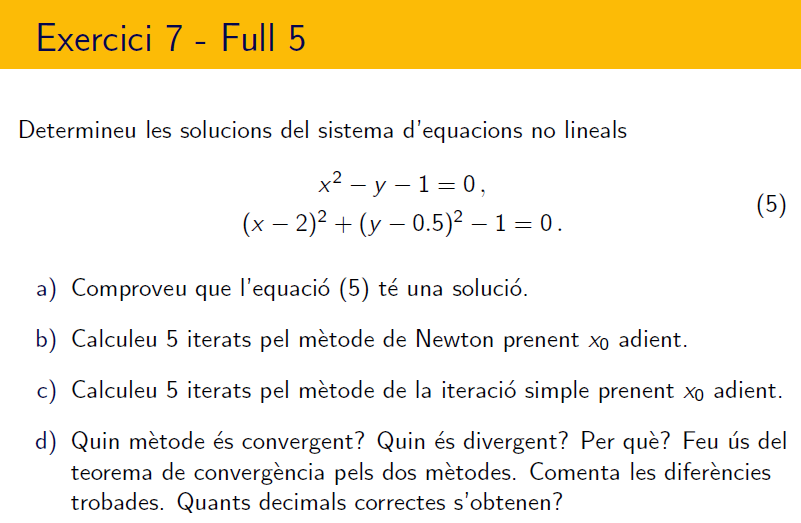

================================================================================

- `Comproveu que el sistema d'equacions té almenys una solució`

F1 = @(x,y) x.^2-y-1

F1 = function_handle with value:
    @(x,y)x.^2-y-1


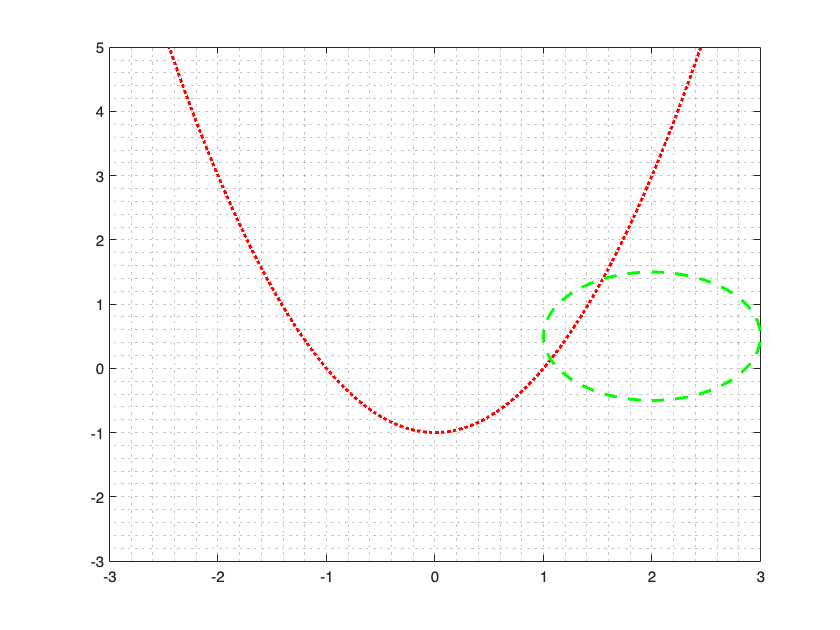

F2 = @(x,y) (x-2).^2+(y-0.5).^2-1;

fimplicit(F1,[-3 3 -3 5],':r','LineWidth',2)
hold on
fimplicit(F2,[-3 3 -3 5],'--g','LineWidth',2),grid minor
hold off

clearvars
options = optimoptions('fsolve','Display','iter','StepTolerance',5e-15,'OptimalityTolerance',5e-15);
x0 = [1.5;1.3];
[x, fval] = fsolve(@myfun,x0,options)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3          0.0146                         0.126               1
     1          6       0.0001625       0.111803           0.02               1
     2          9     8.26415e-09      0.0094839       0.000147               1
     3         12     2.13303e-17    6.76463e-05       7.55e-09               1
     4         15     2.09541e-31    3.42306e-09       1.27e-15               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<<a href = "ma

x =           1.54634288331994
          1.39117631279424


fval =      -4.44089209850063e-16     -1.11022302462516e-16


- `Calculeu 5 iterats pel mètode de Newton, prenent x0 adient`

format longG
x0 = [1.5;1.3]; %escullo una x0 que estigui dins d'un interval proper a l'arrel
[x, fval] = fsolve(@myfun,x0)   


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x =           1.54634288454955
          1.39117631598883


fval =       6.08177508354402e-10      4.57825510835619e-09


myfun(x);
valorBo = x;

F  = @(x,y)[x^2-y-1; (x-2)^2+(y-0.5)^2-1];
F(x0(1),x0(2));
JF = @(x,y)[2*x,-1; 2*(x-2), 2*y-1];
for k=1:5
    y  = linsolve(JF(x0(1),x0(2)),(-F(x0(1),x0(2))));
    x0 = x0+y;
    decimalsCorrectes = min(abs(valorBo'-x0'));

    res(k).y = y;
    res(k).x0 = x0;
    res(k).decimalsCorrectes = decimalsCorrectes;
end

res

res = 1×5 struct array with fields:
    y
    x0
    decimalsCorrectes



F(x0(1),x0(2));

tolF = norm(F(x0(1),x0(2)),'inf');
tolX = norm(y,'inf');
disp(['Solució = ',num2str(x0')])

Solució = 1.5463      1.3912


disp(['tolF = ',num2str(tolF)])

tolF = 2.2204e-16


disp(['tolX = ',num2str(tolX)])

tolX = 2.0961e-16


disp(['Iteracions = ',num2str(k)])

Iteracions = 5


- `Calculeu 5 iterats pel mètode de l'iteració simple, prenent x0 adient`

format longG;
G1 = @(x,y)sqrt(y+1)

G1 = function_handle with value:
    @(x,y)sqrt(y+1)


G2 = @(x,y)sqrt(1-(x-2)^2)+0.5;
%JG = @(x,y)[0,-2*y; -1-y^2, -2*x*y+10]; %es la jacobiana
x0 = [1.5;1.3];
%norm(JG(x0(1),x0(2)),1); %podria ser norma 2
%norm(JG(x0(1),x0(2)),'inf');
for k=1:5
    x0(1) = G1(x0(1),x0(2));
    x0(2) = G2(x0(1),x0(2));
    disp([k,x0']);
end

                         1          1.51657508881031          1.37538583221414

                         2          1.54122867615878          1.38855437223671

                         3          1.54549486321913          1.39074411625326

                         4          1.54620312904006          1.39110515648096

                         5          1.54631987521372           1.3911646000453




%F = @(x,y)[x^2-10*x + y^2 + 8; x*y^2 + x - 10*y + 8];

tolF = norm(F(x0(1),x0(2)),'inf');

disp(['Solució = ',num2str(x0')])

Solució = 1.5463      1.3912


disp(['tolF = ',num2str(tolF)])

tolF = 5.9444e-05


disp(['Iteracions = ',num2str(k)])

Iteracions = 5


- `Compareu els resultats obtinguts amb el resultat de fsolve de MATLAB®. Quants decimals correctes s'obtenen? `

`    Obtinc 8 decimals correctes en el primer i el segon és un mètode divergent`

function F = myfun(x)  
    F(1) = x(1).^2 - x(2) - 1; 
    F(2) = (x(1)-2).^2 + (x(2)-0.5).^2 - 1; 
end

% function valor = iteracioSimple(G, F, Z, iteracions, tolerancia)
%     FZ   = F(Z(1),Z(2)); 
%  
%     tolF = 10^(-6); 
%     tolZ = 10^(-6);
%  
%     k = 0; 
%     while (k < iteracions && (tolF > tolerancia || tolZ > tolerancia))
%         
%         pz   = Z;
%         Z    = G(Z(1),Z(2));
%  
%         tolF = norm(F(Z(1),Z(2)));
%         tolZ = norm(Z-pz);
%         
%         k = k + 1;
%     end
%    
%     valor = Z;
%  
%     disp(['Solució = ',num2str(Z')]);
%     disp(['tolF = ',num2str(tolF)]);
%     disp(['tolZ = ',num2str(tolZ)]);
%     disp(['Iteracions = ',num2str(k)]);
% end